cd /Users/serg/github_projects/QASS_SVM/data
load iris.mat


type='c'; 
l_sig=[0.01:1:12];
l_gam=[0.01:1:12];
l_spl=[];
l_kf=[];
l_leave=[];

i=1; 
for gam=l_gam,
    j=1;
    for sig2=l_sig,
        
    cv1= rsplitvalidate({ Xtrain , Ytrain , type, gam , sig2 , 'RBF_kernel'}, .800 , 'misclass');
    l_spl(i,j)=cv1;
    
    cv2 = crossvalidate({ Xtrain , Ytrain , type, gam , sig2 ,'RBF_kernel'}, 10, 'misclass');
    l_kf(i,j)=cv2;
    
    cv3= leaveoneout({ Xtrain , Ytrain , type, gam , sig2 ,'RBF_kernel'}, 'misclass');
    l_leave(i,j)=cv3;
     
    j=j+1;
    end
    i=i+1;
end

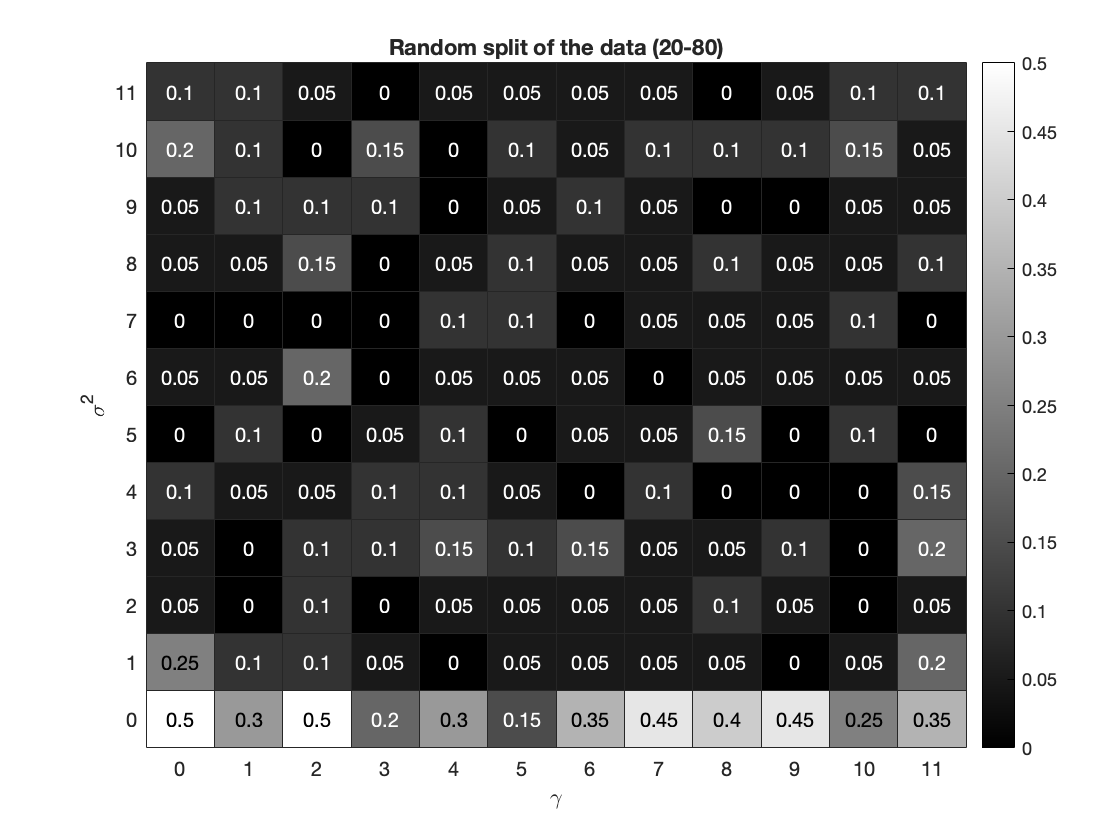

h = heatmap(l_spl);
h.XDisplayLabels = string(round(l_sig));
h.YDisplayLabels = string(round(l_gam));
h.YDisplayData = flipud(h.YDisplayData);
h.NodeChildren(3).YDir='normal';  
title('Random split of the data (20-80)');
xlabel('\gamma');
ylabel('\sigma^2');
colormap(gray);


exportgraphics(h,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_132_1.png','Resolution',300)

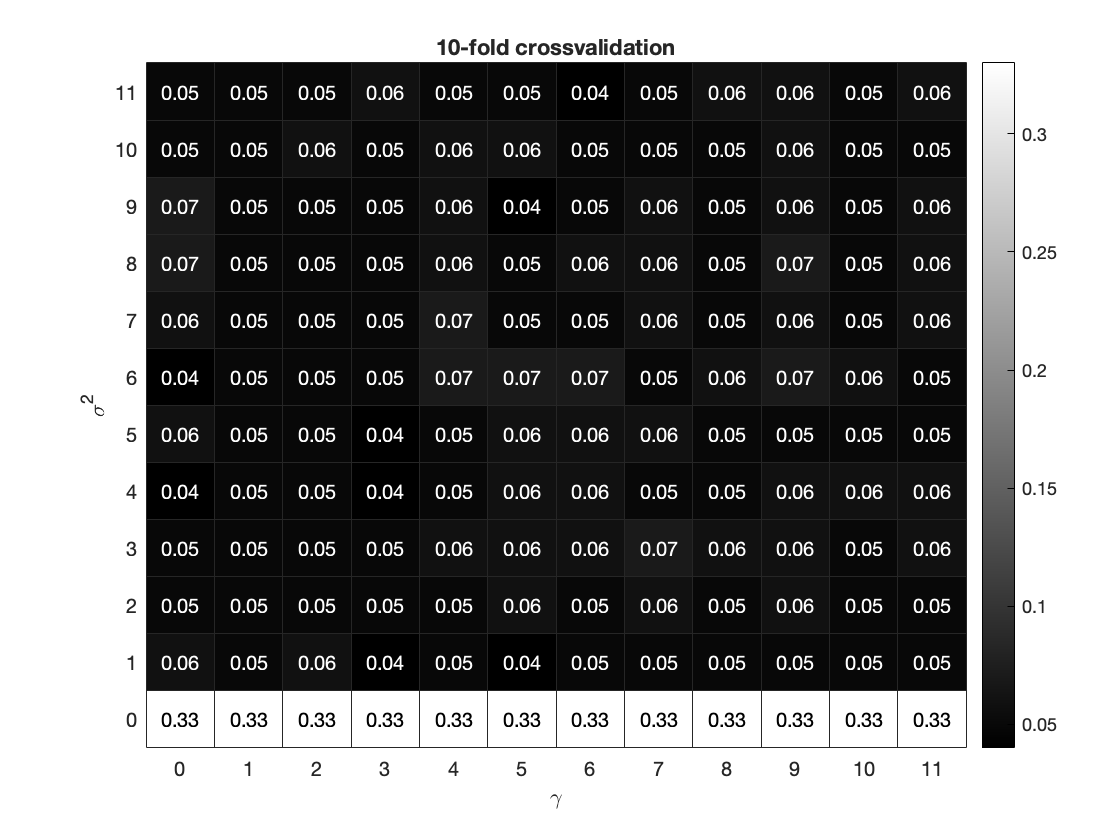

h = heatmap(l_kf);
h.XDisplayLabels = string(round(l_sig));
h.YDisplayLabels = string(round(l_gam));
h.YDisplayData = flipud(h.YDisplayData);
h.NodeChildren(3).YDir='normal';  
title('10-fold crossvalidation');
xlabel('\gamma');
ylabel('\sigma^2');
colormap(gray);


exportgraphics(h,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_132_2.png','Resolution',300)

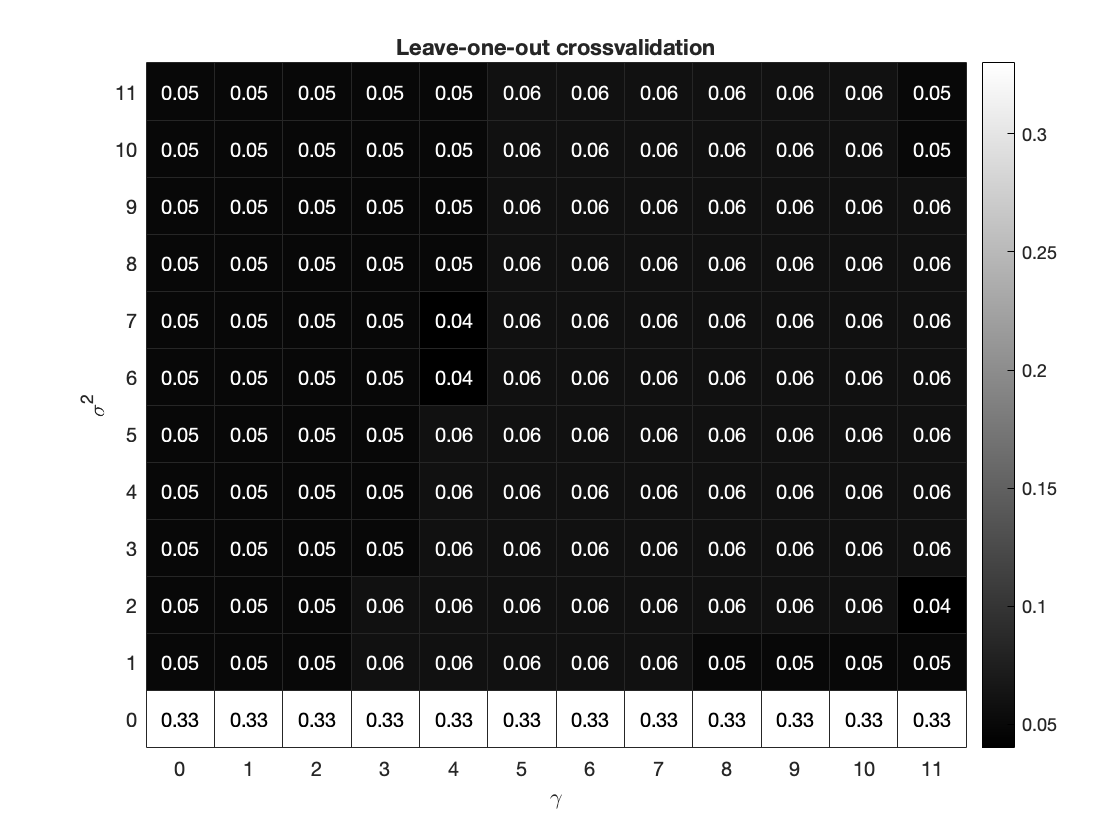

h = heatmap(l_leave);
h.XDisplayLabels = string(round(l_sig));
h.YDisplayLabels = string(round(l_gam));
h.YDisplayData = flipud(h.YDisplayData);
h.NodeChildren(3).YDir='normal';  
title('Leave-one-out crossvalidation');
xlabel('\gamma');
ylabel('\sigma^2');
colormap(gray);


exportgraphics(gcf,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_132_3.png','Resolution',300)